**Project 1: Numerical simulation of a model neuron**

Task 1: Description of a neuron, numerical simulation of a model neuron: solving the system of differential equations using the Runge Kutta 4th order method, analyzing the correctness of choosing the time step.

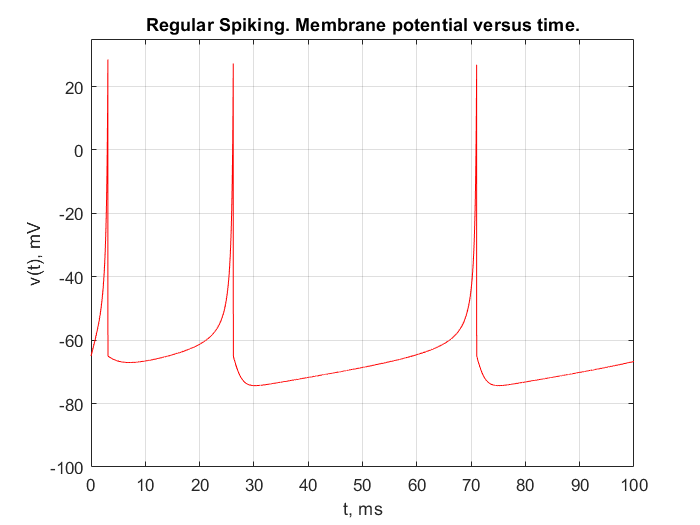

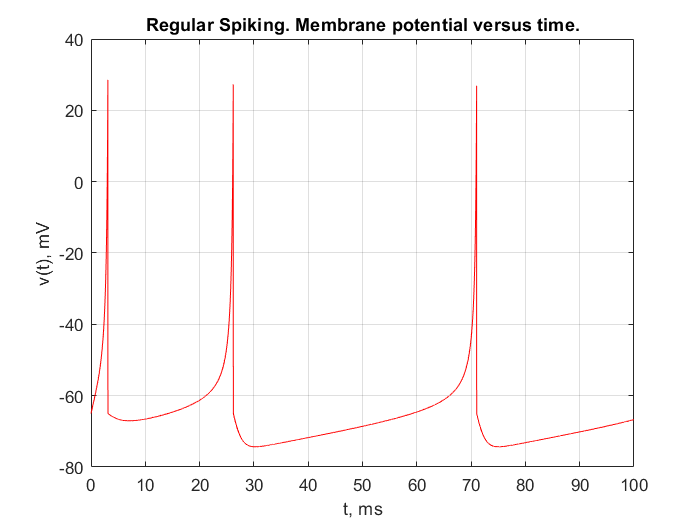

%%% Time %%%
t=100;
dt=0.01;

%%% System parameters %%%
dynamics_regime=1;

% If you selected "own mode", enter your values here.
a=0.1;
b=0.26;
c=-65;
d=2;
I=10;

parameters=[[0.02,0.2,-65,8,10];         
       [0.02,0.2,-55,4,10];
       [0.02,0.2,-50,2,10];
       [0.1,0.2,-65,2,10];
       [0.02,0.25,-65,2,10];
       [0.02,0.25,-65,0.05,10];
       [0.1,0.26,-65,2,10];
       [a,b,c,d,I]];
regime_name=["Regular Spiking","Intrinsically bursting","Chattering","Fast Spiking","Low-threshold spiking","Thalamo-cortical","Rezonator"];
   
[f,dfdt] = Functions_Executions(t,dt,parameters(dynamics_regime,:),regime_name(dynamics_regime),1);

Task 2: Analyzing different regimes of a neuron dynamics, plotting time series and phase portraits of the signal, calculation of a regime map.

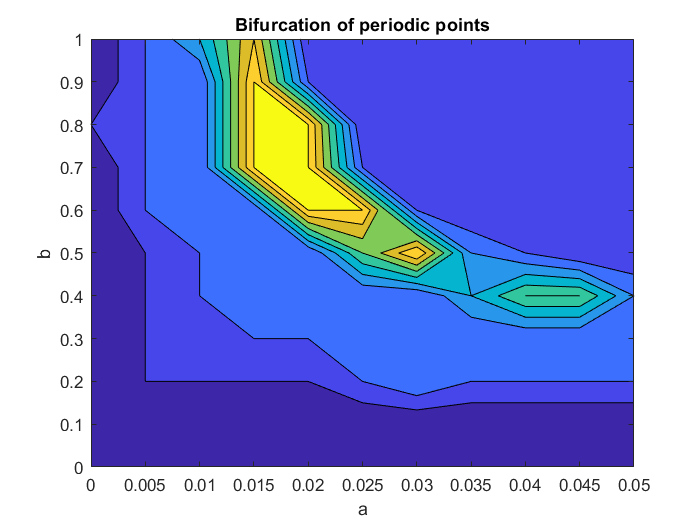

f =      0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     1     1     1     1     2     3     2     2     2     2
     0     1     1     2     2     2     2     2     2     2     2
     0     1     2     2     2     2     2     4     6     6     3
     0     1     2     2     2     6     9     3     2     1     1
     0     2     2     2     9     9     2     1     1     1     1
     0     2     2     9     9     2     1     1     1     1     1
     1     2     2     9     9     1     1     1     1     1     1
     0     2     2     9     2     1     1     1     1     1     1


dfdt =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500
         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500
         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500
         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500
         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500
         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500
         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500
         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500
         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0

%%% System parameters %%%
c=-55;
d=4;
I=10;

grid_pitch=10;
a_max=0.05;
b_max=1;
[f,dfdt] = Functions_Executions(nan,nan,[c,d,I,grid_pitch,a_max,b_max],nan,2);

Task 3: Adding Gaussian noise to the system, solving the system of differential equations with noise, analyzing the influence of noise amplitude on the system dynamics.

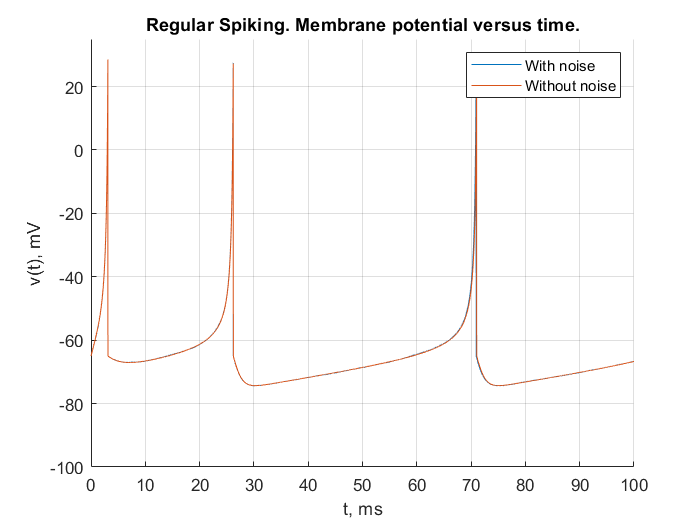

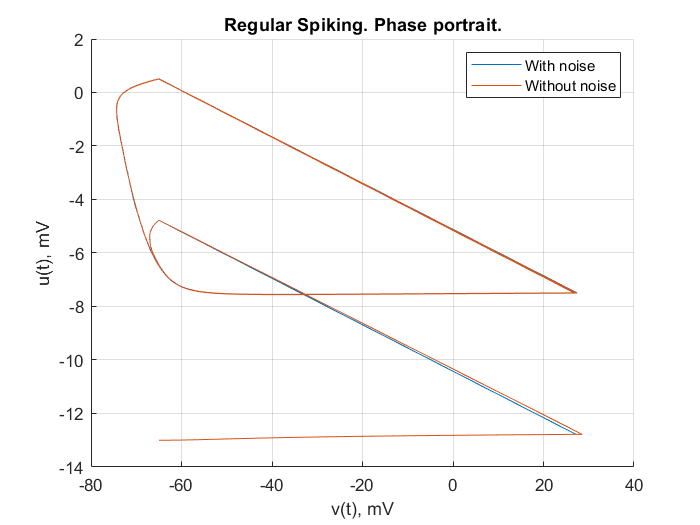

%%% Time %%%
t=100;
dt=0.01;

%%% System parameters %%%
D=1;
dynamics_regime=1;

% If you selected "own mode", enter your values here.
a=0.1;
b=0.26;
c=-65;
d=2;
I=10;

parameters=[[0.02,0.2,-65,8,10];         
       [0.02,0.2,-55,4,10];
       [0.02,0.2,-50,2,10];
       [0.1,0.2,-65,2,10];
       [0.02,0.25,-65,2,10];
       [0.02,0.25,-65,0.05,10];
       [0.1,0.26,-65,2,10];
       [a,b,c,d,I]];
regime_name=["Regular Spiking","Intrinsically bursting","Chattering","Fast Spiking","Low-threshold spiking","Thalamo-cortical","Rezonator"];

[f,dfdt] = Functions_Executions(t,dt,[parameters(dynamics_regime,:),D],regime_name(dynamics_regime),3);

Task 4: Adding the coupling between 2 neurons, analyzing synchronization between neurons for different values of the coupling strength.

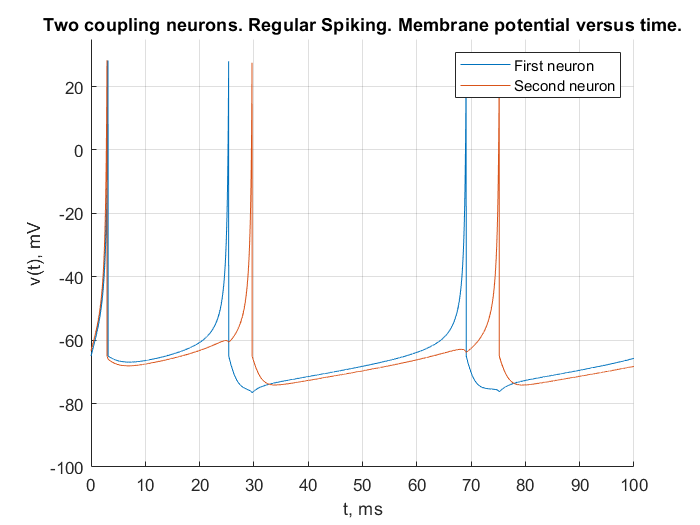

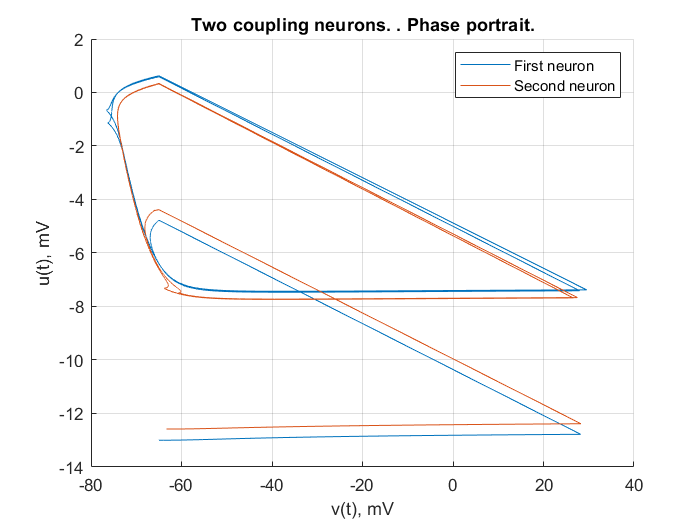

%%% Time %%%
t=100;
dt=0.01;

%%% System parameters %%%
w=-0.05;
dynamics_regime=1;

% If you selected "own mode", enter your values here.
a=0.1;
b=0.26;
c=-65;
d=2;
I=10;

parameters=[[0.02,0.2,-65,8,10];         
       [0.02,0.2,-55,4,10];
       [0.02,0.2,-50,2,10];
       [0.1,0.2,-65,2,10];
       [0.02,0.25,-65,2,10];
       [0.02,0.25,-65,0.05,10];
       [0.1,0.26,-65,2,10];
       [a,b,c,d,I]];
regime_name=["Regular Spiking","Intrinsically bursting","Chattering","Fast Spiking","Low-threshold spiking","Thalamo-cortical","Rezonator"];

[f,dfdt] = Functions_Executions(t,dt,[parameters(dynamics_regime,:),0,w,2],regime_name(dynamics_regime),4);

Task 5: Simulation of a neural network with global topology, analyzing the influence of external stimulus and noise amplitude by calculating characteristic correlation time.

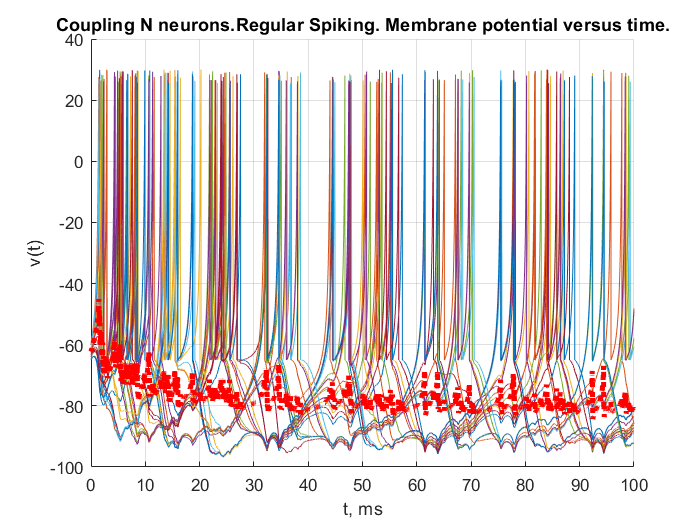

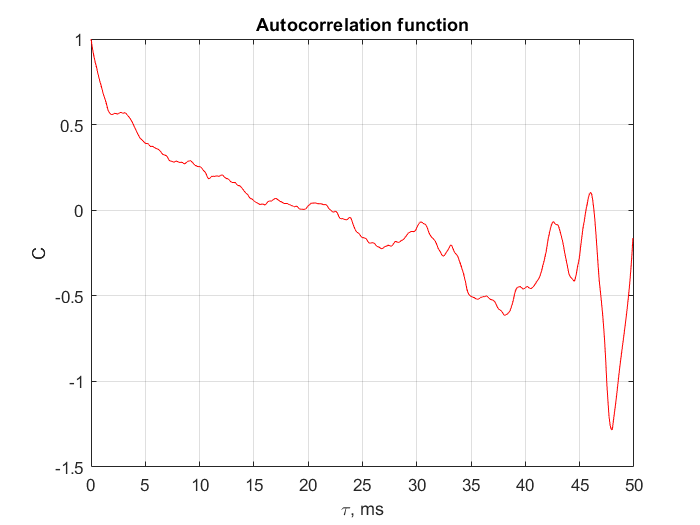

%%% Time %%%
t=100;
dt=0.01;

%%% Autocorrelation parameters %%%
max_tau=50;
dtau=0.1;

%%% System parameters %%%
N=25;
D=1;
w=-0.05;
dynamics_regime=1;

% If you selected "own mode", enter your values here.
a=0.1;
b=0.26;
c=-65;
d=2;
I=10;

parameters=[[0.02,0.2,-65,8,10];         
       [0.02,0.2,-55,4,10];
       [0.02,0.2,-50,2,10];
       [0.1,0.2,-65,2,10];
       [0.02,0.25,-65,2,10];
       [0.02,0.25,-65,0.05,10];
       [0.1,0.26,-65,2,10];
       [a,b,c,d,I]];
regime_name=["Regular Spiking","Intrinsically bursting","Chattering","Fast Spiking","Low-threshold spiking","Thalamo-cortical","Rezonator"];

[f,dfdt] = Functions_Executions(t,dt,[parameters(dynamics_regime,:),D,w,N,max_tau,dtau],regime_name(dynamics_regime),5);